# Stima con multisinusoidi su SCARA. 

Modello giunto 1, coppia-velocità

clc;clear all;close all;
set(0, 'defaultFigurePosition',  [ 1, 1, 800, 600]); % figure più grandi
st=1e-3;
addpath(['..',filesep,'modelli']) %aggiunge al path la cartella modelli (che deve essere nella cartella superiore)

robot=getScaraRobot;


hm=[2 2];
cm=[0 0];
dt=1e-3;
umax=[500; 500];


k=10000*[1 1];
h=2*[1 1];
Jm=[5 5];
system=RoboticSystem(dt,robot,hm,cm,umax,true,Jm,k,h);
system.setForwardDynamics(@fdCodegen_mex)

cs=ControlledSystem(system);

use_close_loop=true;
if (use_close_loop)
    controller=SimpleScaraController(st);
    cs.setController(controller);
end

## Identificazione

Definisco l'azione di controllo come una somma di portante e una sommatoria di sinusoidi. Le sinusoidi devono avere frequenza multipla di quella della portante.

#### Portante

omega_portante=1;
ampiezza_portante=0;  % attrito coloumbiano nullo in questo esempio
T_portante=2*pi/omega_portante;
t=(0:st:(1.1*T_portante))';
portante=ampiezza_portante*sin(omega_portante*t);

#### Multisinusoidi:

Scelgo le sinusoidi come un vettore logaritmicamente spaziato (potrei infittirlo nelle zone di interesse)

w0=0.5;
w1=1500;
omega=logspace(log10(w0),log10(w1),60)';

arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante

Rimuovo duplicati

omega=unique(omega); %scarto eventuali doppioni

Credo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)

multisine_signal=zeros(length(t),1);
for idx=1:length(omega)
    multisine_signal=multisine_signal+sin(omega(idx)*t);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=150;
multisine_signal=multisine_signal/max(multisine_signal)*max_applitude;

Sommo i due segnali applicandoli all'ingresso al giunto 1

exciting_signal=zeros(length(t),system.getInputNumber);
reference=zeros(length(t),system.getOutputNumber);
exciting_signal(:,1)=portante+ multisine_signal;

Non calcolo i coefficienti di Fourier dell'ingresso perchè lo farò sull'azione di controllo dopo la prova

Simulo il sistema


cs.initialize % reinizializza la simulatione

for idx=1:length(t)
    if use_close_loop
        % step: simulo il sisteme in anello chiuso
        [process_output(idx,:),control_action(idx,:),t(idx,1)]=cs.step(reference(idx,:)',exciting_signal(idx,:)');  
        % ingresso 1: riferimento
        % ingresso 2: segnale a valle del controllore
    else
        % openloop: simulo il sisteme in anello aperto
        [process_output(idx,:),t(idx,1)]=cs.openloop(exciting_signal(idx,:));
        control_action(idx,:)=exciting_signal(idx,:);
    end
end

figure
subplot(3,2,1)

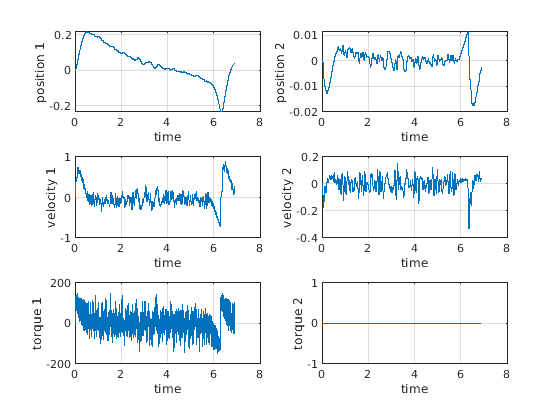

plot(t,process_output(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t,process_output(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t,exciting_signal(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t,process_output(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t,process_output(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t,exciting_signal(:,2))
xlabel('time')
ylabel('torque 2')
grid on

Calcolo i coefficienti di Fourier dell'uscita

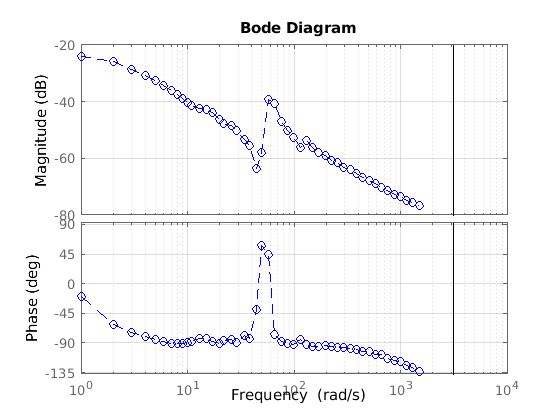

process_output_coef=fourierCoefficients(t,process_output(:,3),omega_portante,omega);
control_action_coef=fourierCoefficients(t,control_action(:,1),omega_portante,omega);
freq_resp=idfrd(process_output_coef./control_action_coef,omega,st); % Y(i*omega)/U(i*omega)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';
figure
bodeplot(freq_resp,'--o', bode_opts);
grid on
hold on

Stima modello (potrei farla a mano)

peso=ones(length(freq_resp.Frequency),1);
wpeso0=10;
wpeso1=2000;
peso(freq_resp.Frequency<wpeso0)=1e-5;
peso(freq_resp.Frequency>wpeso1)=1e-5;
 
opts=ssestOptions('WeightingFilter',peso,'EnforceStability',1);
md = ssest(freq_resp,3,'Ts',st,opts);

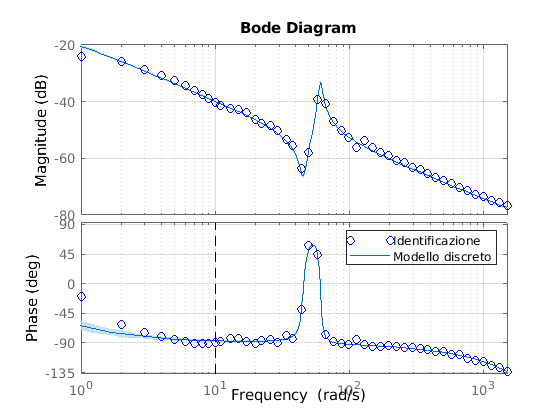

figure


bode_handle=bodeplot(freq_resp,'o', bode_opts);
showConfidence(bode_handle,3)
hold on
bode(md, bode_opts)
xlim([omega(1) omega(end)])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
grid on
legend('Identificazione','Modello discreto')
grid on

## Validazione

Definisco l'azione di controllo come una somma di portante e una sommatoria di sinusoidi. Le sinusoidi devono avere frequenza multipla di quella della portante.

#### Portante

omega_portante=2;
T_portante=2*pi/omega_portante;
t_vali=(0:st:(1.1*T_portante))';
portante=0*sin(omega_portante*t_vali);

#### Multisinusoidi:

Scelgo le sinusoidi come un vettore composto da due pacchi di sinusoidi

omega=sort([logspace(log10(5),log10(1000),10)' ; ...
            logspace(log10(10),log10(100),10)']);

arrotondo a dei multipli della portante

omega=round(omega/omega_portante)*omega_portante; % arrotondo per avere le omega multiple della portante

Rimuovo duplicati

omega=unique(omega); %scarto eventuali doppioni

Credo il segnale come somma di sinusoidi (qui suppongo ampiezza costante per ogni pulsazione, nulla mi impedisce di fare diversamente)

multisine_signal=zeros(length(t_vali),1);
for idx=1:length(omega)
    multisine_signal=multisine_signal+sin(omega(idx)*t_vali);
end

Impongo che l'ampiezza del segnale sia quella desiderata

max_applitude=20;
multisine_signal=multisine_signal/max(multisine_signal)*max_applitude;

Sommo i due segnali

exciting_signal_vali=zeros(length(t_vali),system.getInputNumber);
exciting_signal_vali(:,1)=portante+ multisine_signal;
reference_vali=zeros(length(t_vali),system.getOutputNumber);

Simulo il sistema

cs.initialize
for idx=1:length(t_vali)
    if use_close_loop
        [process_output_vali(idx,:),control_action_vali(idx,:),t(idx,1)]=cs.step(reference_vali(idx,:)',exciting_signal_vali(idx,:)');
    else
        [process_output_vali(idx,:),t(idx,1)]=cs.openloop(exciting_signal_vali(idx,:));
        control_action_vali(idx,:)=exciting_signal(idx,:);
    end
end


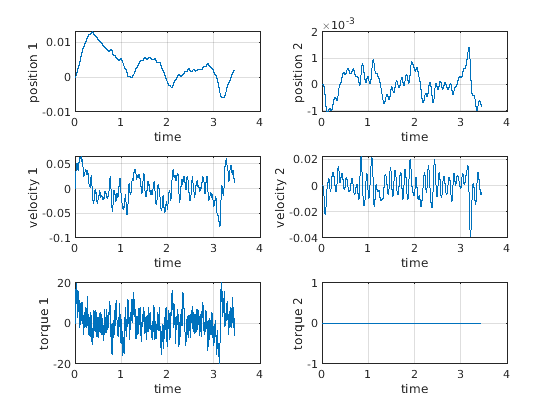

figure
subplot(3,2,1)
plot(t_vali,process_output_vali(:,1))
xlabel('time')
ylabel('position 1')
grid on

subplot(3,2,3)
plot(t_vali,process_output_vali(:,3))
xlabel('time')
ylabel('velocity 1')
grid on

subplot(3,2,5)
plot(t_vali,exciting_signal_vali(:,1))
xlabel('time')
ylabel('torque 1')
grid on

subplot(3,2,2)
plot(t_vali,process_output_vali(:,2))
xlabel('time')
ylabel('position 2')
grid on

subplot(3,2,4)
plot(t_vali,process_output_vali(:,4))
xlabel('time')
ylabel('velocity 2')
grid on

subplot(3,2,6)
plot(t_vali,exciting_signal_vali(:,2))
xlabel('time')
ylabel('torque 2')
grid on

Calcolo i coefficienti di Fourier dell'uscita e dell'ingresso

process_output_coef_vali=fourierCoefficients(t_vali,process_output_vali(:,3),omega_portante,omega);
control_action_coef_vali=fourierCoefficients(t_vali,control_action_vali(:,1),omega_portante,omega);
freq_resp_validazione=idfrd(process_output_coef_vali./control_action_coef_vali,omega,st); % Y(i*omega)/U(i*omega)
bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';


Diagramma di Bode Validazione

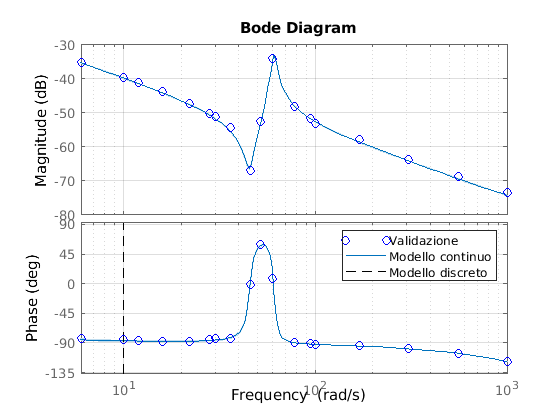

figure

bode_handle=bodeplot(freq_resp_validazione,'o', bode_opts);
showConfidence(bode_handle,3)
hold on
bode(md, bode_opts)
xlim([omega(1) omega(end)])
plot([wpeso0 wpeso0],ylim,'--k')
plot([wpeso1 wpeso1],ylim,'--k')
grid on

legend('Validazione','Modello continuo','Modello discreto')